# Project 5

**Name: Joshua Jackson**

**Date: 12/13/2022**

## **Table of Contents:**

#### **Problem Statement**

#### **Part I: Plotting Flow vs. Diameter**

#### **Part II: Transform to Linear Relationship**

#### **Part III: Multiple Linear Regression**

#### **Part IV: Estimate the Flow**

#### **Part V: Quadratic Interpolation (Newton's Method)**

#### **Part VI: Verifying Newton's Method Graphically**

#### **Part VII: Quadratic Interpolation (Lagrange Method)**

#### **Part VIII: Verifying the Lagrange Method Graphically**

#### **Discussion and Conclusion**

#### **Appendix**

## **Problem Statement: **

A mechanical engineering study indicates that the fluid flow through a pipe is related to pipe diameter and slope. In this project, you will be given experimental data for diameter, slope, and flow of circular concrete pipes. You will first use least-squares linear regression to find a nonlinear relationship of the flow and both diameter and slope as two independent variables. Then you will use quadratic interpolation on the data to model the flow by fixing one of the independent variables. 

The experimental data are shown in the table below:

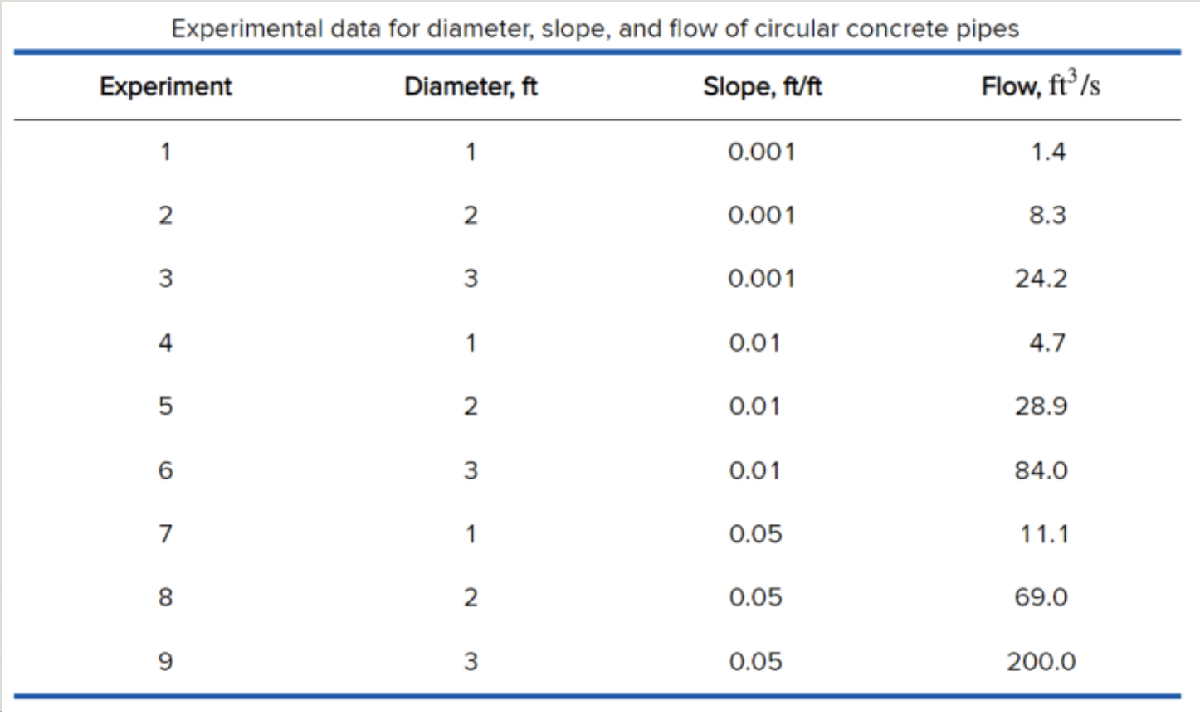

## **Part I: Plotting Flow vs Diameter**

Plot the flow Q (ft^3/s) versus both the pipe diameter D (ft) and the slope (ft/ft) using MATLAB command mesh. In this case, the vertices of the mesh lines are the triples (D(j), S(i), Q(i,j)). Note that D corresponds to the columns of Q and S corresponds to the rows of Q.

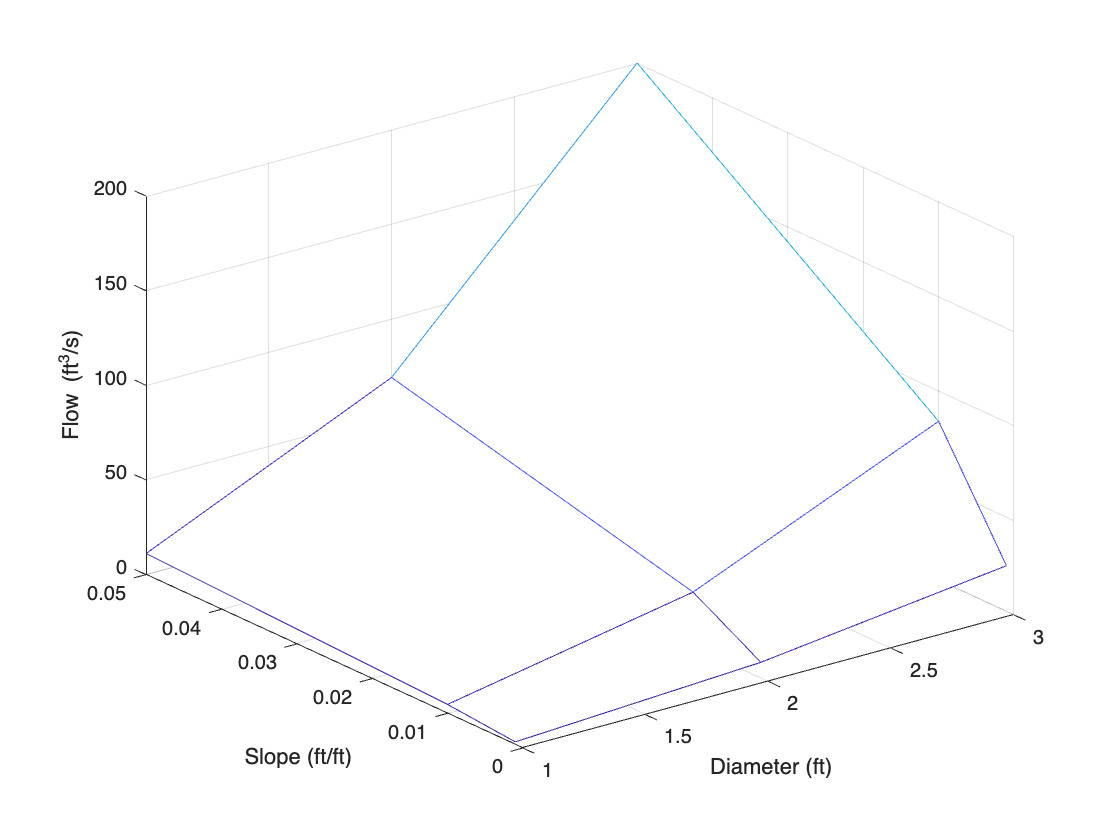

Q = [1.4 8.3 24.2; 4.7 28.9 84.0; 11.1 69.0 200.0];
D = [1 2 3 1 2 3 1 2 3];
S = [0.001 0.001 0.001 0.01 0.01 0.01 0.05 0.05 0.05];
X = [1 2 3]; % Column Values (Diameter) : X
Y = [0.001 0.01 0.05]; % Row Values (Slope) : Y

mesh(X, Y, Q)
hold on
xlabel('Diameter (ft)')
ylabel('Slope (ft/ft)')
zlabel('Flow (ft^3/s)')
hold off

**Results**: The graph above shows that as the diameter (ft) or the slope (ft/ft) increases, the flow (ft^3/s) increases as well. The diameter and slope are both directly proportional to the flow. 

## **Part II: Transform to Linear Relationship**

Consider the nonlinear function below with two independent variables: 

Transform this nonlinear relationship to linear relationship by taking the logarithm of the equation.

Q = [1.4 8.3 24.2 4.7 28.9 84.0 11.1 69.0 200.0];
D = [1 2 3 1 2 3 1 2 3];
S = [0.001 0.001 0.001 0.01 0.01 0.01 0.05 0.05 0.05];
% Transform the nonlinear relationship using the logarithm
log_D = log(D);
log_S = log(S);
log_Q = log(Q);

**Results**: The nonlinear relationship was transformed into a linear relationship through the use of the logarithm. The coefficients a0, a1, and a2 were found using multiple linear regression, outlined in Part III below.

## **Part III: Multiple Linear Regression**

Perform multiple linear regression on the transformed data and obtain the coefficients a0, a1, a2. (Hint: refer to Homework Assignment 7.6)

x1 = log_D;
x2 = log_S;
y = log_Q;
n = length(y);

% compute the sums and assign them to the A matrix elements
A(1,1) = n;
A(1,2) = sum(x1); 
A(1,3) = sum(x2); 
A(2,1) = A(1,2); 
A(2,2) = sum(x1.*x1);
A(2,3) = sum(x1.*x2);
A(3,1) = A(1,3); 
A(3,2) = A(2,3);
A(3,3) = sum(x2.*x2);

% compute the sums and assign them to the b vector elements
b(1) = sum(y);
b(2) = sum(x1.*y);
b(3) = sum(x2.*y);

% obtain a0, a1, a2 from a
a = inv(A)*b';
log_a0 = a(1);
a0 = exp(log_a0)

a0 = 55.9719

a1 = a(2)

a1 = 2.6158

a2 = a(3)

a2 = 0.5368

**Results**: Using the results for a0, a1, and a2, found through multiple linear regression, the function with two independent variables is:


$$Q\left(D,S\right)=55\ldotp 9719D^{2\ldotp 6158} S^{0\ldotp 5368}$$


## **Part IV: Estimate the Flow**

Use the model you obtained from Part III, estimate the flow Q at i) D = 2.5ft, S = 0.01 ft/ft; ii) D = 2ft, S = 0.025 ft/ft; iii) D = 2.5ft, S = 0.025 ft/ft.

D_spec = [2.5 2 2.5];
S_spec = [0.01 0.025 0.025];
Q_est = a0*D_spec.^(a1).*S_spec.^(a2)

Q_est =    51.9229   47.3657   84.9113


**Results**: The flow at D = 2.5 ft and S = 0.01 ft/ft is Q = **51.9229 ft^3/s.**

The flow at D = 2 ft and S = 0.025 ft/ft is Q = **47.3657 ft^3/s.**

The flow at D = 2.5 ft and S = 0.025 ft/ft is Q = **84.9113 ft^3/s.**

## **Part V: Quadratic Interpolation (Newton's Method)**

Perform quadratic interpolation using Newton's divided difference method on the data with D0 = 1ft, D1 = 2ft, D2 = 3ft and S = 0.01 ft/ft. That is, to compute the coefficienct b0, b1, b2 in the second-order polynomial below: 

D_n = [1 2 3];
Q_n = [4.7 28.9 84.0];
[b,Q_est] = Newtint(D_n,Q_n, 2.5)

b =     4.7000   24.2000   15.4500


Q_est = 52.5875

**Results**: Using quadratic interpolation with Newton's method with D = 1, 2, and 3, Q = 4.7, 28.9, and 84, the estimated flow was found to be Q = 52.5875 and the coefficients were found to be b0 = 4.7, b1 = 24.2, and b2 = 15.45.

If these coefficients are input into the equation above, the equation becomes:


$$Q\left(D\right)=4\ldotp 7+24\ldotp 2\left(D-D_0 \right)+15\ldotp 45\left(D-D_0 \right)\left(D-D_1 \right)$$
 

With the values D = 1, 2, and 3, the equation becomes


$$Q\left(D\right)=4\ldotp 7+24\ldotp 2\left(D-1\right)+15\ldotp 45\left(D-1\right)\left(D-2\right)$$


As mentioned above, the interpolated value of the dependent variable was found to be


$$Q\left(D\right)=52\ldotp 5875\;\frac{{\textrm{ft}}^3 }{s}$$


## **Part VI: Verifying Newton's Method Graphically**

Verify the model from Part V with a plot showing Q(D) from Part V, Q(D,S) from Part III with S = 0.01 ft/ft, and the experimental data with S = 0.01 ft/ft. Estimate the flow Q at D = 2.5ft,  S = 0.01 ft/ft. Compare it with the result in Part IV i).

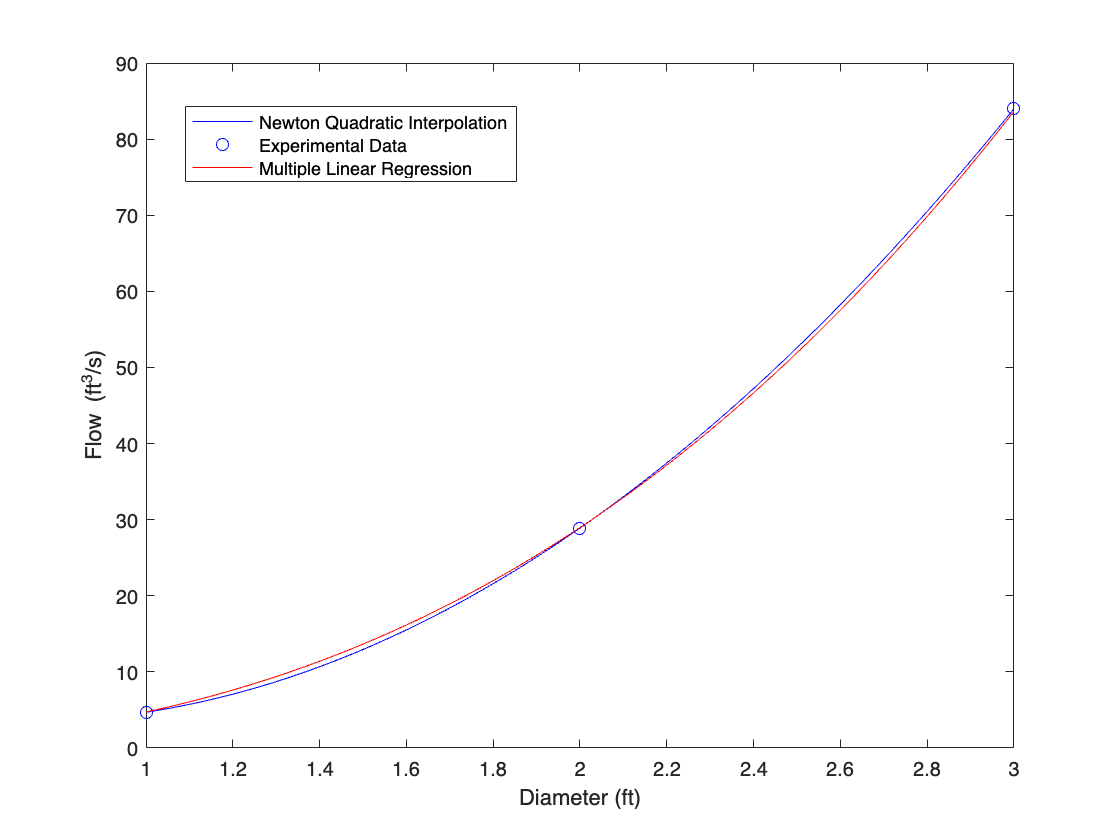

D_p = linspace(1,3,50);
Q1 = (b(1)+b(2).*(D_p-D(1))+b(3).*(D_p-D(1)).*(D_p-D(2)));
Qds = a0.*D_p.^a1.*0.01.^a2;
plot(D_p,Q1,'b-')
hold on
Q2 = (b(1)+b(2).*(D-D(1))+b(3).*(D-D(1)).*(D-D(2)));
plot(D,Q2,'bo')
plot(D_p,Qds,'r-')
xlabel('Diameter (ft)')
ylabel('Flow (ft^3/s)')
legend('Newton Quadratic Interpolation','Experimental Data','Multiple Linear Regression')
legend("Position",[0.16518,0.78368,0.29643,0.090476])
hold off

**Results**: As seen in the graph above, the flow from part V, shown by the blue line, the flow estimated in part III, shown by the red line, and the data points when S = 0.01 ft/ft, are all very similar analytically. This shows the effectiveness of Newton's quadratic interpolation method. 

## **Part VII: Quadratic Interpolation (Lagrange Method)**

Perform quadratic interpolation using the Lagrange method on the data with D = 2ft and S0 = 0.001 ft/ft, S1 = 0.01 ft/ft, S2 = 0.05 ft/ft. That is, to compute the coefficients c0, c1, c2 in the second-order polynomial below:

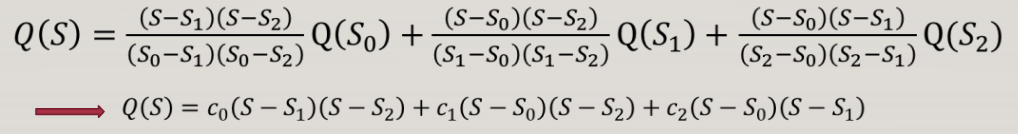

S_1 = [0.001 0.01 0.05];
Q_1 = [8.3 28.9 69];
[c,yint] = Lagrange(S_1,Q_1,0.025)

c = 1.0e+04 *

    1.8821   -8.0278    3.5204


yint = 53.7823

**Results**: Through using the Lagrange method to perform quadratic interpolation, the c coefficients were found to be c0 = 1.8821 x 10^4, c1 = -8.0278 x 10^4, and c2 = 3.5204 x 10^4. Because of this, the equation above becomes: 


$$Q\left(S\right)=1\ldotp 8821{\mathrm{x10}}^4 \left(S-S_1 \right)\left(S-S_2 \right)+-8\ldotp 0278{\mathrm{x10}}^4 \left(S-S_0 \right)\left(S-S_2 \right)+3\ldotp 5204{\mathrm{x10}}^4 \left(S-S_0 \right)\left(S-S_1 \right)$$


The interpolated value of the dependent variable was found to be yint = 53.7823

## **Part VIII: Verifying the Lagrange Method Graphically**

Verify the model from Part VII with a plot showing Q(S) from Part VII, Q(D,S) from Part III with D = 2 ft/ft, and the experimental data with D = 2ft. Use the model you obtained from Part VII, estimate the flow Q at D = 2ft, S = 0.025 ft/ft. Compare it with the result in Part IV ii).

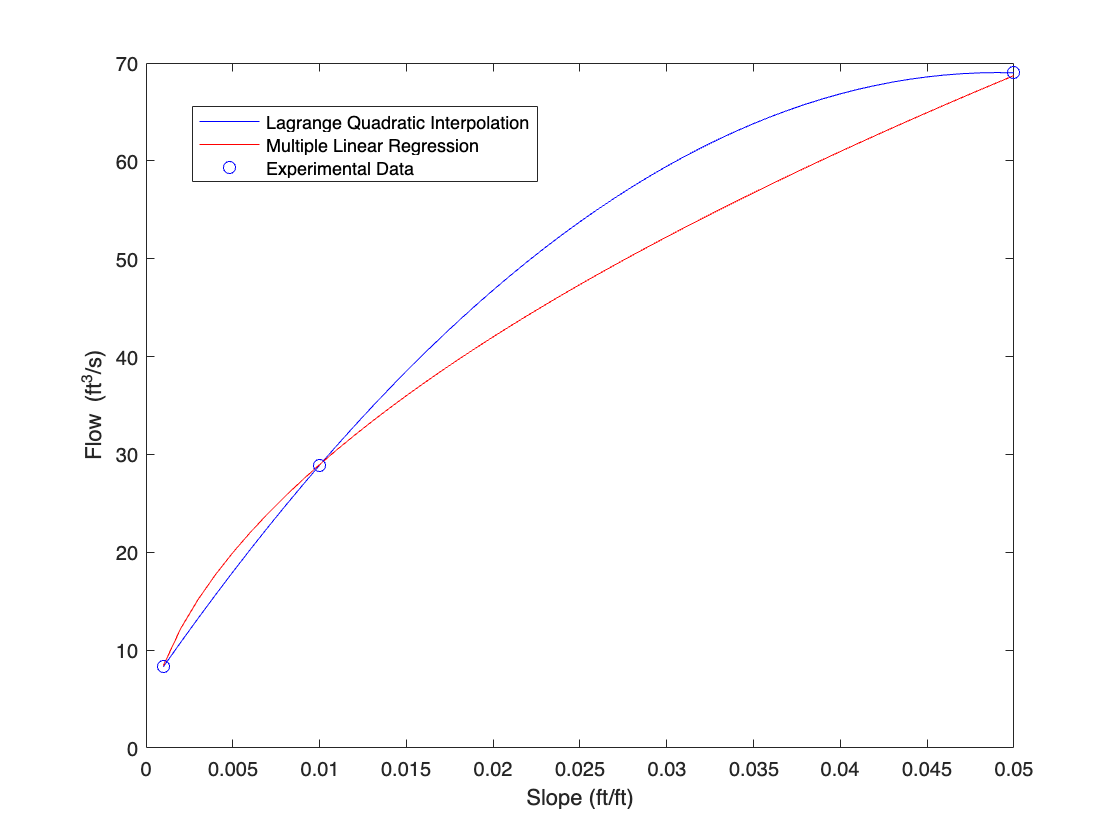

S_p = linspace(0.001,0.05,50);
Qs = c(1).*(S_p-S_1(2)).*(S_p-S_1(3))+c(2).*(S_p-S_1(1)).*(S_p-S_1(3))+c(3).*(S_p-S_1(1)).*(S_p-S_1(2));
plot(S_p,Qs,'b-')
S = [0.001 0.01 0.05];
Q = [8.3 28.9 69];
hold on
Q2 = (b(1)+b(2).*(D-D(1))+b(3).*(D-D(1)).*(D-D(2)));
Qds = a0.*2.^a1.*S_p.^a2;
plot(S_p,Qds,'r-')
plot(S,Q,'bo')
xlabel('Slope (ft/ft)')
ylabel('Flow (ft^3/s)')
legend('Lagrange Quadratic Interpolation','Multiple Linear Regression','Experimental Data')
legend("Position",[0.17108,0.78336,0.30893,0.090476])
hold off

**Results**: As seen in the graph above, the flow from part VII, shown by the blue line, the flow estimated in part III, shown by the red line, and the data points when D = 2 ft, are in some ways similar graphically. The relationship is not as evident when compared the previous graph, but there remains an obvious trend in the lines and data points. The reason that the lines are slightly off is because the data points have a large 'empty' gap between the slop values of 0.01 and 0.05 ft/ft. Although the lines aren't perfectly similar, their general similarity shows the effectiveness of Lagrange quadratic interpolation method. 

## Discussion and Conclusion

    The nonlinear relationship was first transformed into a linear relationship through the use of the logarithm function. The coefficients a0, a1, and a2, of this transformed equation were found to be a0 = 55.9719, a1 = 2.6158, and a2 = 0.5368. When these coefficients were plugged into the equation, it became $Q\left(D,S\right)=55\ldotp 9719D^{2\ldotp 6158} S^{0\ldotp 5368}$. Using this model, flow Q at i) D = 2.5ft, S = 0.01 ft/ft; ii) D = 2ft, S = 0.025 ft/ft; iii) D = 2.5ft, S = 0.025 ft/ft was estimated. The estimated flow was found to be Q = 51.9229 ft^3/s, 47.3657 ft^3/s, and 84.9113 ft^3/s respectively. 

    Using Newton's quadratic interpolation method, the coeffiecents b0, b1, and b2 were found to be b0 = 4.7, b1 = 24.2, and b2 = 15.45. When plugged into the equation from part V, it became $Q\left(D\right)=4\ldotp 7+24\ldotp 2\left(D-D_0 \right)+15\ldotp 45\left(D-D_0 \right)\left(D-D_1 \right)$. The interpolated value of the dependent variable was found to be $Q\left(D\right)=52\ldotp 5875\;\frac{{\mathrm{ft}}^3 }{s}$ through Newton's method. Newton's method was then verified graphically and shown to be a good fit for the experimental data and the equation found through part III. 

    The Lagrange method for quadratic interpolation was then used and the coefficients c0, c1, and c2 were found to be c0 = 1.8821 x 10^4, c1 = -8.0278 x 10^4, and c2 = 3.5204 x 10^4. Because of this, the equation in part VII became $Q\left(S\right)=1\ldotp 8821{\mathrm{x10}}^4 \left(S-S_1 \right)\left(S-S_2 \right)+-8\ldotp 0278{\mathrm{x10}}^4 \left(S-S_0 \right)\left(S-S_2 \right)+3\ldotp 5204{\mathrm{x10}}^4 \left(S-S_0 \right)\left(S-S_1 \right)$. The interpolated value of the dependent variable was doun to be yint = 53.7823 through the Lagrange method. The Lagrange method was verified graphically and shown to be a near fit to the equation discovered through part III. When compared to one another, the Newton and Lagrange quadratic interpolation methods differ only slightly. As shown through the graphs and discussions of results above, Newton's method performed better when producing a polynomial to fit the data points. 

    Some problems faced through this project were getting the graphs, including the verification graphs, to look good. It took me a long time to realize that I needed to use the MATLAB linspace built-in function to graph the data. Another problem I faced was manipulating the data so that the correct equations could be computed. The flow had to be made into a 3x3 matrix in order to be graphed using the MATLAB mesh function, and then it had to be changed back into a vector to be used in the further sections of the project. Through this project I learned many things about quadratic interpolation and the use of MATLAB to obtain satisfiable results. 

## Appendix

#### Function used to compute Newton's Interpolating Polynomial

function [b,yint] = Newtint(x,y,xx)
% Newtint: Newton interpolating polynomial
% yint = Newtint(x,y,xx): Uses an (n - 1)-order Newton
%   interpolating polynomial based on n data points (x, y)
%   to determine a value of the dependent variable (yint)
%   at a given value of the independent variable, xx.
% input:
%   x = independent variable
%   y = dependent variable
%   xx = value of independent variable at which
%        interpolation is calculated
% output:
%   yint = interpolated value of dependent variable
% compute the finite divided differences in the form of a
% difference table
n = length(x);
if length(y)~=n, error('x and y must be same length'); end
A = zeros(n,n);
% assign dependent variables to the first column of b.
A(:,1) = y(:); % the (:) ensures that y is a column vector.
for j = 2:n
  for i = 1:n-j+1
    A(i,j) = (A(i+1,j-1)-A(i,j-1))/(x(i+j-1)-x(i));
  end
end
% coefficients in the polynomial
b(:) = A(1,:);
% use the finite divided differences to interpolate
xt = 1;
yint = b(1);
for j = 1:n-1
  xt = xt*(xx-x(j));
  yint = yint+b(j+1)*xt;
end
end

#### Function Used to compute the Lagrange Interpolating Polynomial

function [c, yint] = Lagrange(x,y,xx)
% Lagrange: Lagrange interpolating polynomial
%   yint = Lagrange(x,y,xx): Uses an (n - 1)-order
%     Lagrange interpolating polynomial based on n data points
%     to determine a value of the dependent variable (yint) at
%     a given value of the independent variable, xx.
% input:
%   x = independent variable
%   y = dependent variable
%   xx = value of independent variable at which the
%        interpolation is calculated
% output:
%   c = coefficients in the polynomial
%   yint = interpolated value of dependent variable
n = length(x);
if length(y)~=n, error('x and y must be same length'); end
s = 0;
for i = 1:n
  c(i) = y(i);
  product = y(i);
  for j = 1:n
    if i ~= j
      c(i) = c(i)/(x(i)-x(j));
      product = product*(xx-x(j))/(x(i)-x(j));
    end
  end
  s = s+product;
end
yint = s;
end
